%% 1번 문제
clear; clc;

% (a) 
rng(13);

% (b) 
p = 0.35 + (0.95 - 0.35) * rand(1, 40);

% (c)
num_students = 5000;
num_questions = 40;
rand_matrix = rand(num_students, num_questions);
results = rand_matrix <= p; % 크기 브로드캐스팅 적용 (5000x40 <= 1x40)

% (d) 
total_scores = sum(results, 2); 
mean_score = mean(total_scores);
std_score = std(total_scores);

fprintf('=== 1번 결과 ===\n');

=== 1번 결과 ===


fprintf('학생들의 평균 총점: %.2f 개\n', mean_score);

학생들의 평균 총점: 25.84 개


fprintf('학생들의 총점 표준편차: %.2f\n', std_score);

학생들의 총점 표준편차: 2.81



% (e) 
above_mean_ratio = mean(total_scores >= mean_score);
fprintf('평균점수 이상인 학생의 비율: %.2f%%\n', above_mean_ratio * 100);

평균점수 이상인 학생의 비율: 56.40%


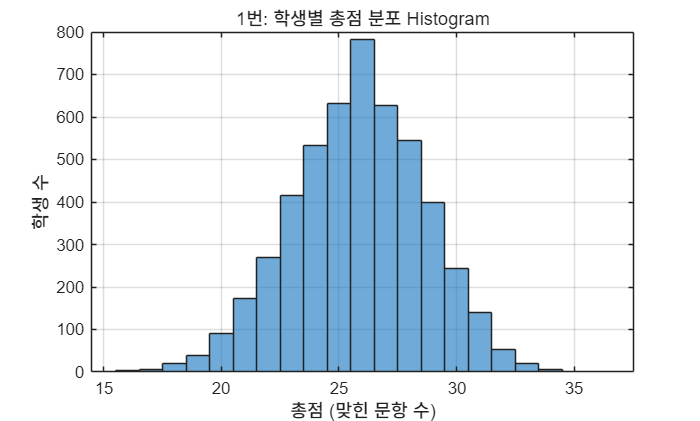


figure(1);
histogram(total_scores, 'BinMethod', 'integers');
title('1번: 학생별 총점 분포 Histogram');
xlabel('총점 (맞힌 문항 수)');
ylabel('학생 수');
grid on;